# Ecoli: revision de datos paso a paso

Cada seccion deja una tabla en el workspace lista para abrir en Classification Learner (Apps > Classification Learner > New Session > From Workspace, y en Response se escoge "clase"). Se corre una seccion, se entrenan todos los modelos, se toma el pantallazo, y se sigue.

clear; close all; clc

## Paso 0: cargar y mirar el dato crudo

336 proteinas, 7 medidas y la clase (sitio de la celula donde queda).

T = readtable('../data/ecoli/ecoli.data', 'FileType', 'text', 'Delimiter', ' ', ...
              'MultipleDelimsAsOne', true, 'ReadVariableNames', false);
T.Properties.VariableNames = {'nombre','mcg','gvh','lip','chg','aac','alm1','alm2','clase'};
T.nombre = [];                      % es un codigo, no sirve para clasificar
T.clase = categorical(T.clase);

T0_crudo = T;
disp(head(T0_crudo))

    mcg     gvh     lip     chg    aac     alm1    alm2    clase
    ____    ____    ____    ___    ____    ____    ____    _____

    0.49    0.29    0.48    0.5    0.56    0.24    0.35     cp  
    0.07     0.4    0.48    0.5    0.54    0.35    0.44     cp  
    0.56     0.4    0.48    0.5    0.49    0.37    0.46     cp  
    0.59    0.49    0.48    0.5    0.52    0.45    0.36     cp  
    0.23    0.32    0.48    0.5    0.55    0.25    0.35     cp  
    0.67    0.39    0.48    0.5    0.36    0.38    0.46     cp  
    0.29    0.28    0.48    0.5    0.44    0.23    0.34     cp  
    0.21    0.34    0.48    0.5    0.51    0.28    0.39     cp  



summary(T0_crudo)


T0_crudo: 336×8 table

Variables:

    mcg: double
    gvh: double
    lip: double
    chg: double
    aac: double
    alm1: double
    alm2: double
    clase: categorical (8 categories)

Statistics for applicable variables:

             NumMissing       Min          Median         Max           Mean          Std    

    mcg          0                0        0.5000        0.8900        0.5001        0.1946  
    gvh          0           0.1600        0.4700             1        0.5000        0.1482  
    lip          0           0.4800        0.4800             1        0.4955        0.0885  
    chg          0           0.5000        0.5000             1        0.5015        0.0273  
    aac          0                0        0.4950        0.8800        0.5000        0.1224  
    alm1         0           0.0300        0.4550             1        0.5002        0.2158  
    alm2         0                0        0.4300        0.9900        0.4997        0.2094  
    clase        0  

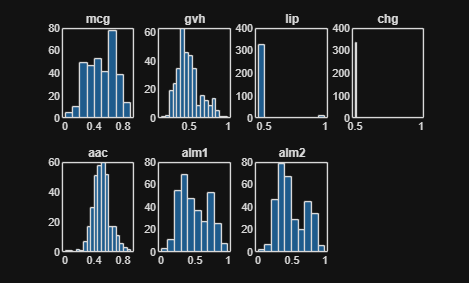


% distribucion de cada variable
figure('Name', 'Histogramas crudo');
vars = {'mcg','gvh','lip','chg','aac','alm1','alm2'};
for k = 1:7
    subplot(2,4,k); histogram(T.(vars{k})); title(vars{k});
end

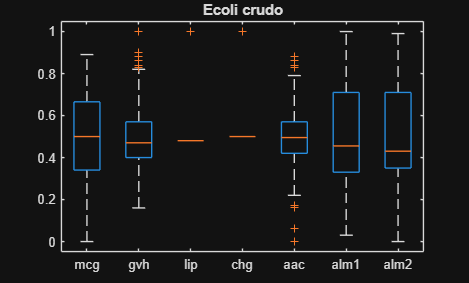


% boxplot de todas juntas (estan todas entre 0 y 1, se pueden comparar)
figure('Name', 'Boxplot crudo');
boxplot(T{:, vars}, 'Labels', vars); title('Ecoli crudo');

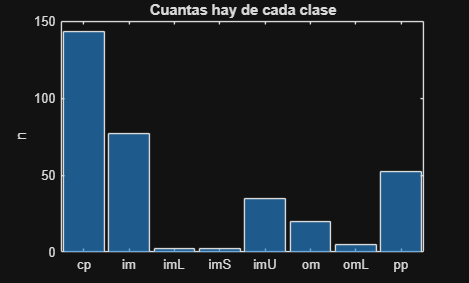


% balance de la clase
figure('Name', 'Balance de clases');
histogram(T.clase); title('Cuantas hay de cada clase'); ylabel('n');

disp(countcats(T.clase)')

   143    77     2     2    35    20     5    52



disp(categories(T.clase)')

    {'cp'}    {'im'}    {'imL'}    {'imS'}    {'imU'}    {'om'}    {'omL'}    {'pp'}




% Lo que se ve: chg es casi constante (335 de 336 valen 0.5), lip solo toma
% dos valores, y hay clases con 2 y 5 muestras. La clase esta muy
% desbalanceada: cp tiene 143 y imL tiene 2.

## Paso 1: corregir outliers

Regla del 1.5*IQR: lo que se sale del rango se recorta al borde (no se borra la fila, que con 336 datos no sobran). Solo en las variables continuas. chg se quita porque es casi constante.

T1_outliers = T0_crudo;
T1_outliers.chg = [];
continuas = {'mcg','gvh','aac','alm1','alm2'};
for k = 1:numel(continuas)
    x = T1_outliers.(continuas{k});
    q = quantile(x, [0.25 0.75]);
    li = q(1) - 1.5*(q(2)-q(1));
    ls = q(2) + 1.5*(q(2)-q(1));
    fprintf('%s: %d valores fuera de [%.2f, %.2f]\n', continuas{k}, sum(x<li | x>ls), li, ls);
    x(x < li) = li;  x(x > ls) = ls;
    T1_outliers.(continuas{k}) = x;
end

mcg: 0 valores fuera de [-0.15, 1.15]
gvh: 13 valores fuera de [0.15, 0.82]
aac: 9 valores fuera de [0.20, 0.79]
alm1: 0 valores fuera de [-0.24, 1.28]
alm2: 0 valores fuera de [-0.19, 1.25]


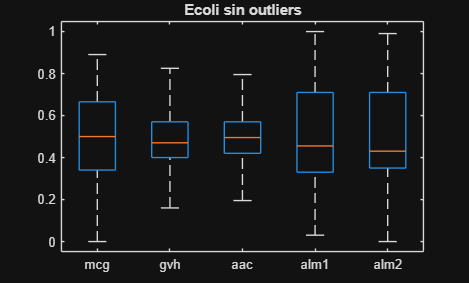


figure('Name', 'Boxplot sin outliers');
boxplot(T1_outliers{:, continuas}, 'Labels', continuas); title('Ecoli sin outliers');

## Paso 2: balancear las clases

Las clases con menos de 10 muestras (imL, imS, omL) no se pueden aprender ni validar, se quitan. Las demas se igualan a la mas grande repitiendo filas al azar (sobremuestreo).

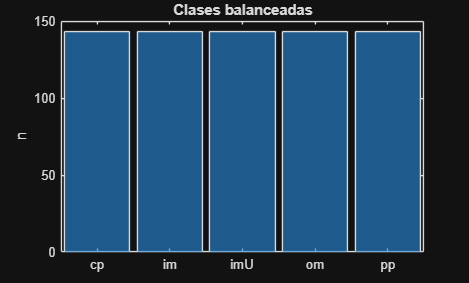

rng(1)
T2_balanceado = T1_outliers;
n = countcats(T2_balanceado.clase);
c = categories(T2_balanceado.clase);
T2_balanceado(ismember(T2_balanceado.clase, c(n < 10)), :) = [];
T2_balanceado.clase = removecats(T2_balanceado.clase);

c = categories(T2_balanceado.clase);
n_max = max(countcats(T2_balanceado.clase));
extra = table();
for k = 1:numel(c)
    filas = T2_balanceado(T2_balanceado.clase == c{k}, :);
    faltan = n_max - height(filas);
    extra = [extra; filas(randi(height(filas), faltan, 1), :)]; %#ok<AGROW>
end
T2_balanceado = [T2_balanceado; extra];

figure('Name', 'Balance despues');
histogram(T2_balanceado.clase); title('Clases balanceadas'); ylabel('n');

fprintf('Antes: %d filas y %d clases. Despues: %d filas y %d clases.\n', ...
    height(T1_outliers), numel(categories(T1_outliers.clase)), ...
    height(T2_balanceado), numel(c));

Antes: 336 filas y 8 clases. Despues: 715 filas y 5 clases.


## Paso 3: estandarizar (media 0, desviacion 1)

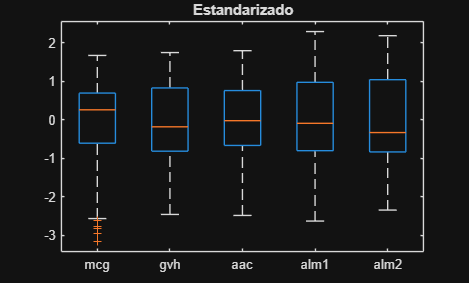

T3_estandarizado = T2_balanceado;
for k = 1:numel(continuas)
    T3_estandarizado.(continuas{k}) = zscore(T2_balanceado.(continuas{k}));
end
figure('Name', 'Boxplot estandarizado');
boxplot(T3_estandarizado{:, continuas}, 'Labels', continuas); title('Estandarizado');

## Paso 4: normalizar (entre 0 y 1)

Ojo: se parte del balanceado, no del estandarizado. Son dos opciones distintas para comparar, no dos pasos seguidos.

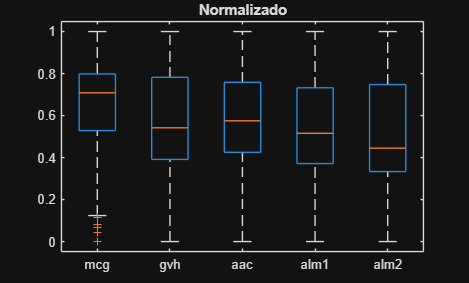

T4_normalizado = T2_balanceado;
for k = 1:numel(continuas)
    x = T2_balanceado.(continuas{k});
    T4_normalizado.(continuas{k}) = (x - min(x)) / (max(x) - min(x));
end
figure('Name', 'Boxplot normalizado');
boxplot(T4_normalizado{:, continuas}, 'Labels', continuas); title('Normalizado');

## Resumen de lo que hay en el workspace

disp('Tablas listas para Classification Learner (Response = clase):')

Tablas listas para Classification Learner (Response = clase):


disp({'T0_crudo'; 'T1_outliers'; 'T2_balanceado'; 'T3_estandarizado'; 'T4_normalizado'})

    {'T0_crudo'        }
    {'T1_outliers'     }
    {'T2_balanceado'   }
    {'T3_estandarizado'}
    {'T4_normalizado'  }

